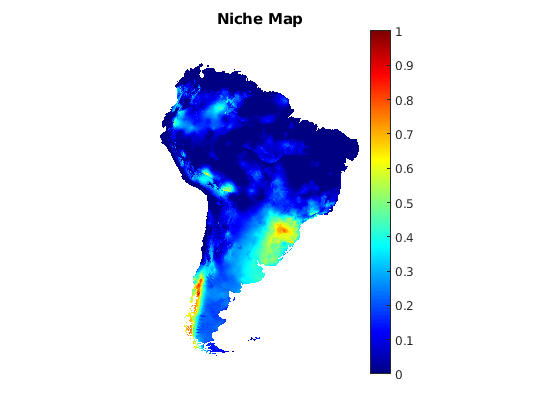

load("ModelMap.mat")
load("NicheMap.mat")

figure
geoshow(NicheMap,R,'DisplayType','surface') 
colormap jet
colorbar
axis off ; 
title("Niche Map")

NewModelMetric = MapMetric(NicheMap, ModelMap, false);
disp(NewModelMetric)

    0.7159    0.8043



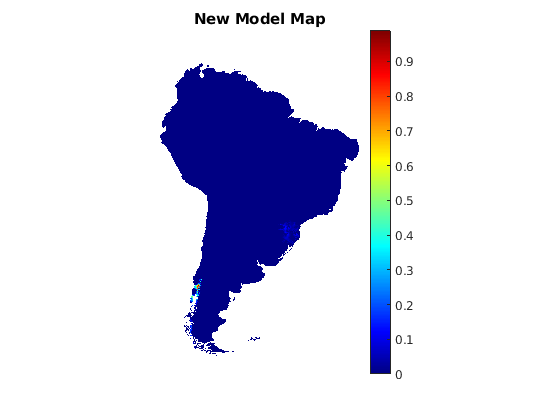

figure
geoshow(ModelMap,R,'DisplayType','surface') 
colormap jet
colorbar
axis off ; 
title("New Model Map")

Algorithm: GenSP_1_bioclim.asc


    0.7159    0.8032



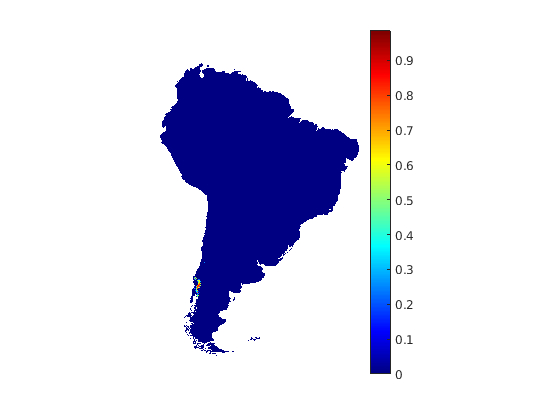

Algorithm: GenSP_1_brt.asc


    0.8162    0.8656



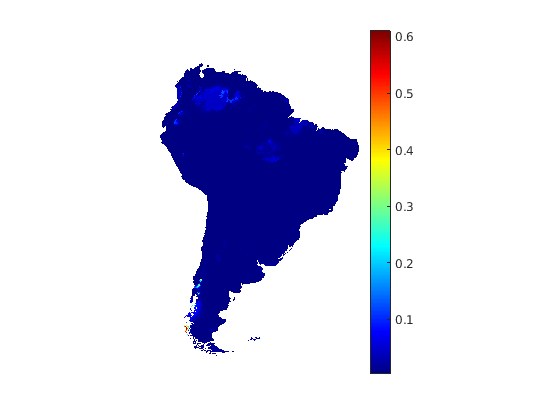

Algorithm: GenSP_1_cart.asc


    0.8232    0.8555



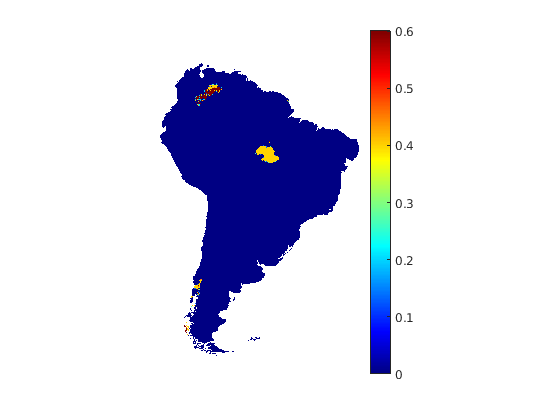

Algorithm: GenSP_1_domain.asc


    0.7173    0.8095



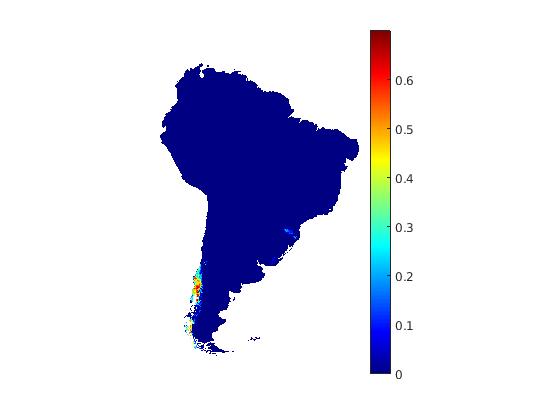

Algorithm: GenSP_1_fda.asc


    0.8097    0.8708



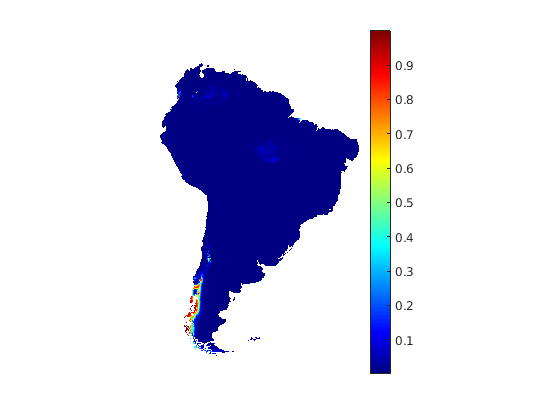

Algorithm: GenSP_1_gam.asc


    0.8033    0.8645



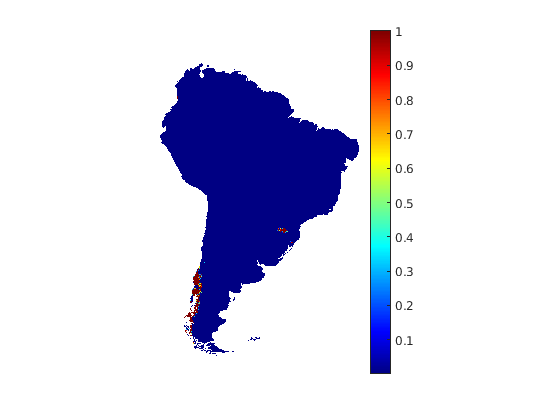

Algorithm: GenSP_1_glm.asc


    0.8039    0.8657



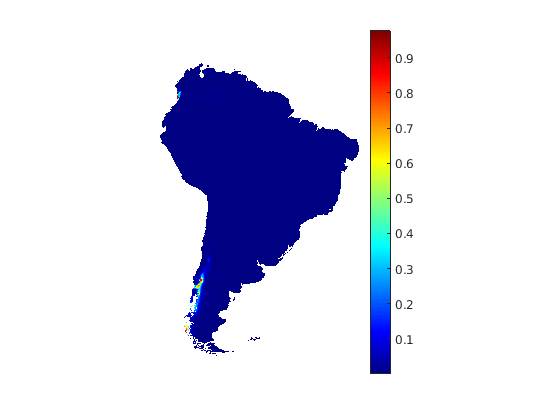

Algorithm: GenSP_1_mars.asc


    0.8091    0.8649



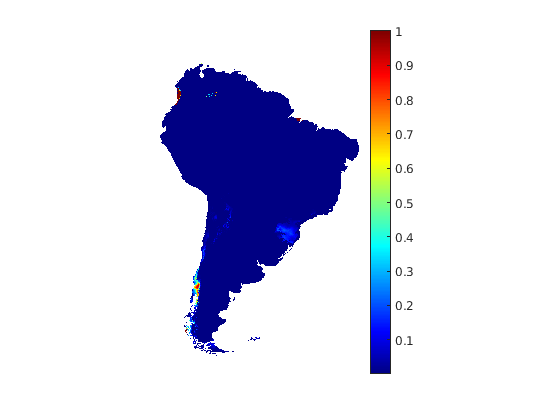

Algorithm: GenSP_1_maxent.asc


    0.8164    0.8788



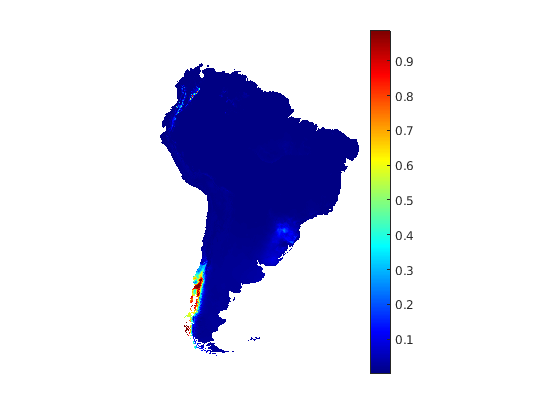

Algorithm: GenSP_1_maxlike.asc


    0.8813    0.7567



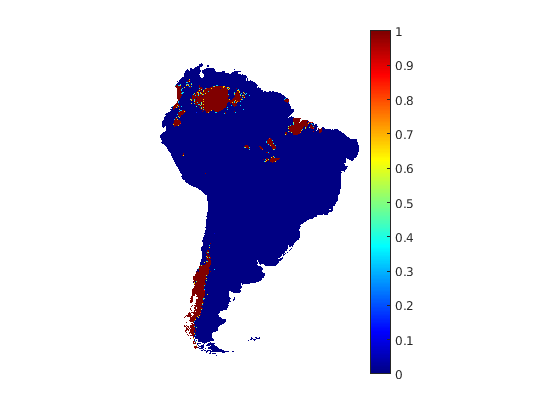

Algorithm: GenSP_1_mda.asc


    0.8071    0.8692



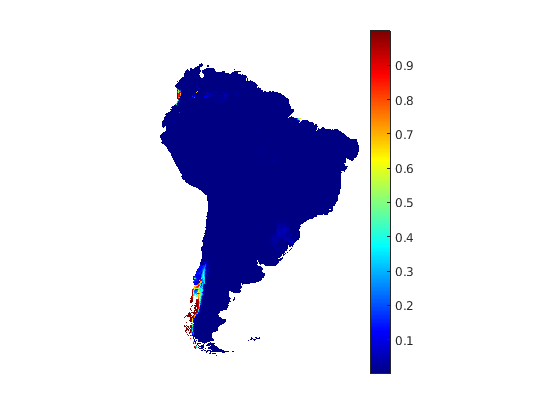

Algorithm: GenSP_1_rf.asc


    0.8069    0.8676



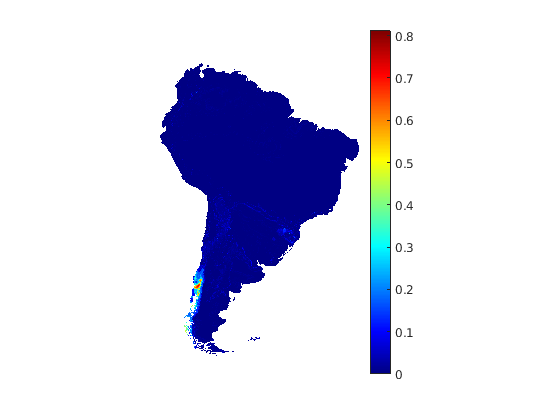

Algorithm: GenSP_1_svm.asc


    0.8227    0.8641



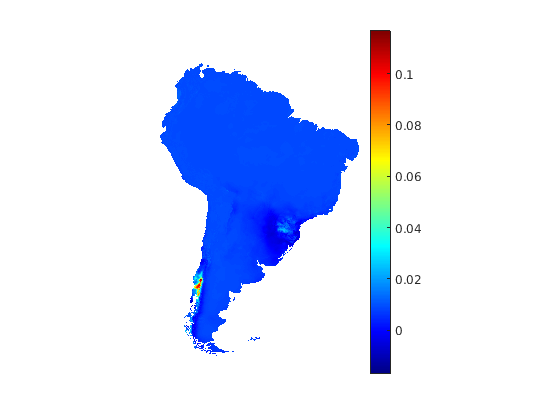

myDir ="/home/curie/MATLAB-Drive/VirtualSpecies/Prueba_Algoritmos_worst/";
myFiles = dir(fullfile(myDir,"*.asc"));
Table=[];

for k = 1:length(myFiles)
  baseFileName(k) = convertCharsToStrings(myFiles(k).name);
  fprintf(1, 'Algorithm: %s\n', baseFileName(k));
  [ModelMap, R] =  arcgridread(baseFileName(k));
  Table(k,:) = MapMetric(NicheMap, ModelMap, false);
  disp(Table(k,:));
  figure
  geoshow(ModelMap,R,'DisplayType','surface')  
  colormap jet
  colorbar
  axis off ; 
  drawnow
end

baseFileName(end+1)="New Algorithm";
Table(end+1,:) = NewModelMetric;

[~, idx] = sort(Table);

disp("Distance")

Distance


for i=1:length(Table)
 disp(baseFileName(idx(i,2))+": "+num2str(Table(idx(i,2),2)))
end

GenSP_1_maxlike.asc: 0.75673
GenSP_1_bioclim.asc: 0.80323
New Algorithm: 0.80425
GenSP_1_domain.asc: 0.80952
GenSP_1_cart.asc: 0.85555
GenSP_1_svm.asc: 0.86415
GenSP_1_gam.asc: 0.86449
GenSP_1_mars.asc: 0.86487
GenSP_1_brt.asc: 0.86558
GenSP_1_glm.asc: 0.86568
GenSP_1_rf.asc: 0.86757
GenSP_1_mda.asc: 0.86922
GenSP_1_fda.asc: 0.87083
GenSP_1_maxent.asc: 0.87883


disp("Area")

Area


for i=1:length(Table)
 disp(baseFileName(idx(i,1))+": "+num2str(Table(idx(i,1),1)))
end

GenSP_1_bioclim.asc: 0.71587
New Algorithm: 0.71591
GenSP_1_domain.asc: 0.7173
GenSP_1_gam.asc: 0.80333
GenSP_1_glm.asc: 0.80392
GenSP_1_rf.asc: 0.80688
GenSP_1_mda.asc: 0.80714
GenSP_1_mars.asc: 0.80911
GenSP_1_fda.asc: 0.80967
GenSP_1_brt.asc: 0.81623
GenSP_1_maxent.asc: 0.81644
GenSP_1_svm.asc: 0.82272
GenSP_1_cart.asc: 0.82318
GenSP_1_maxlike.asc: 0.88132
